# Meta 4: Análise em Tempo–Frequência via STFT

## Exercício 21: Carrega a estrutura de dados

clear; clc; close all;
load('AED1.mat','tabela');   % espera-se que 'tabela' contenha Sinal_Processado e Taxa_Amostragem

% Parâmetros gerais
digitosUnicos = unique(tabela.Digito);
nDigits       = numel(digitosUnicos);


## Exercício 22: Cálculo e Visualização da STFT para cada dígito

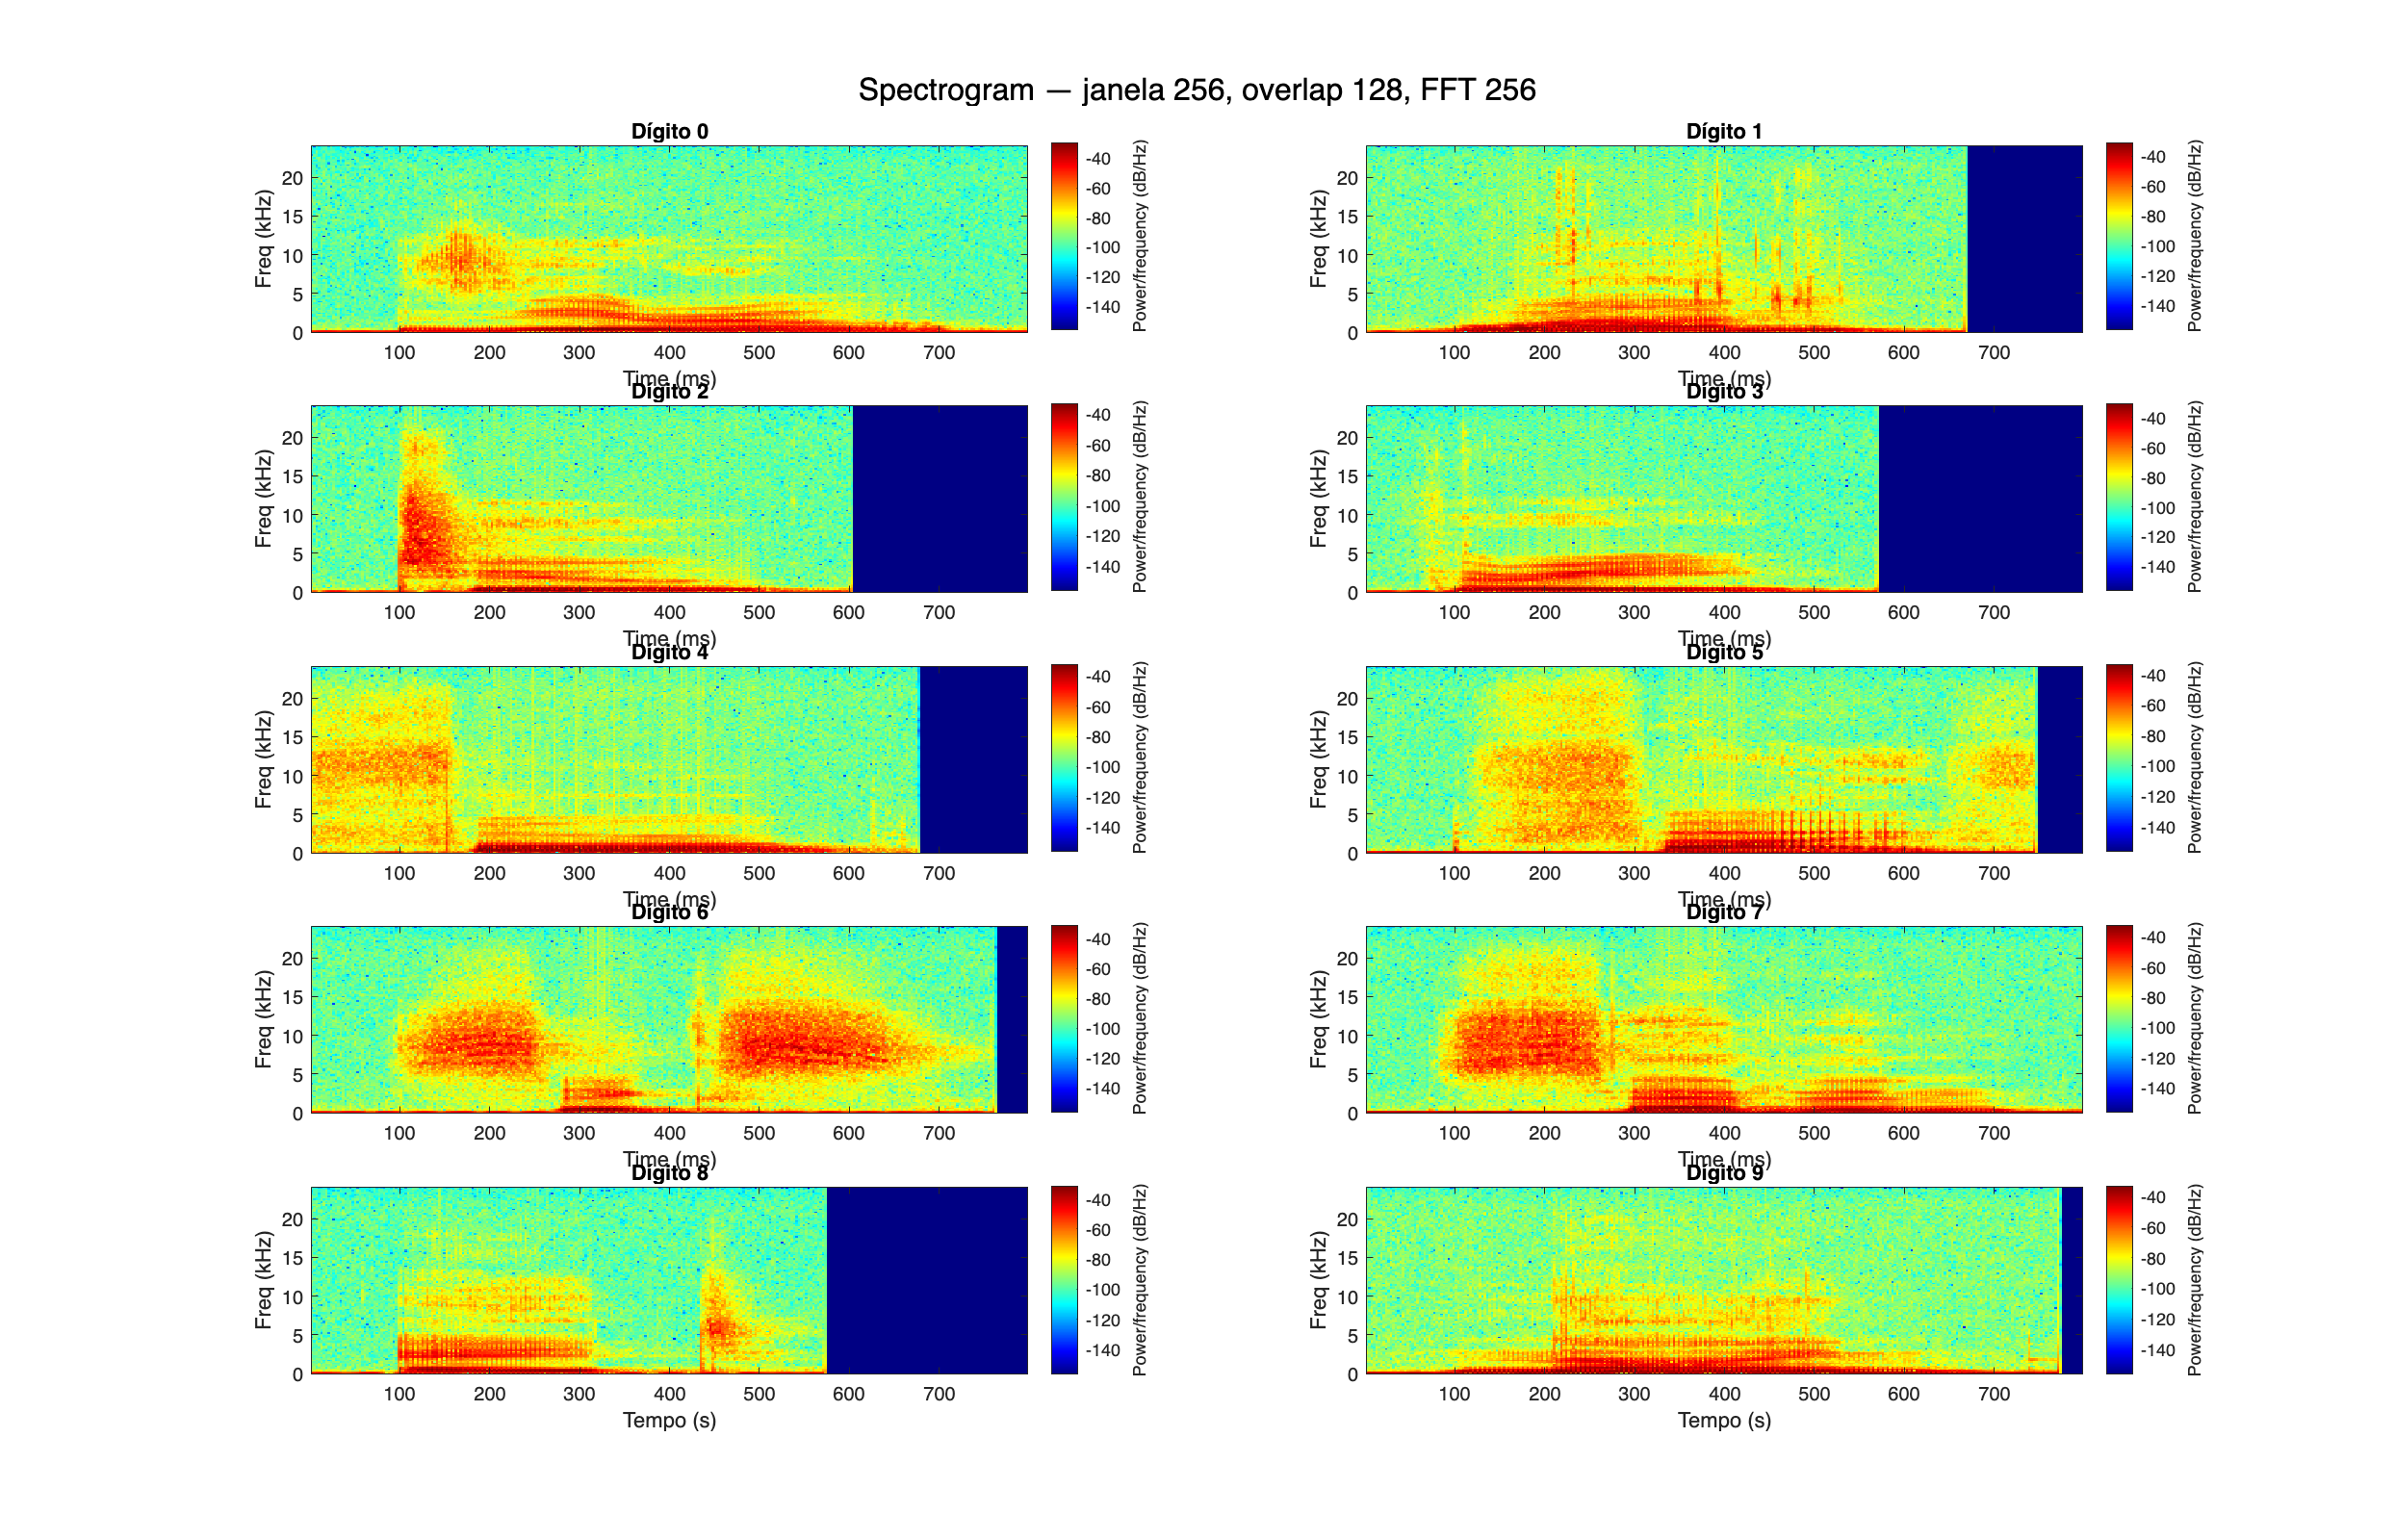

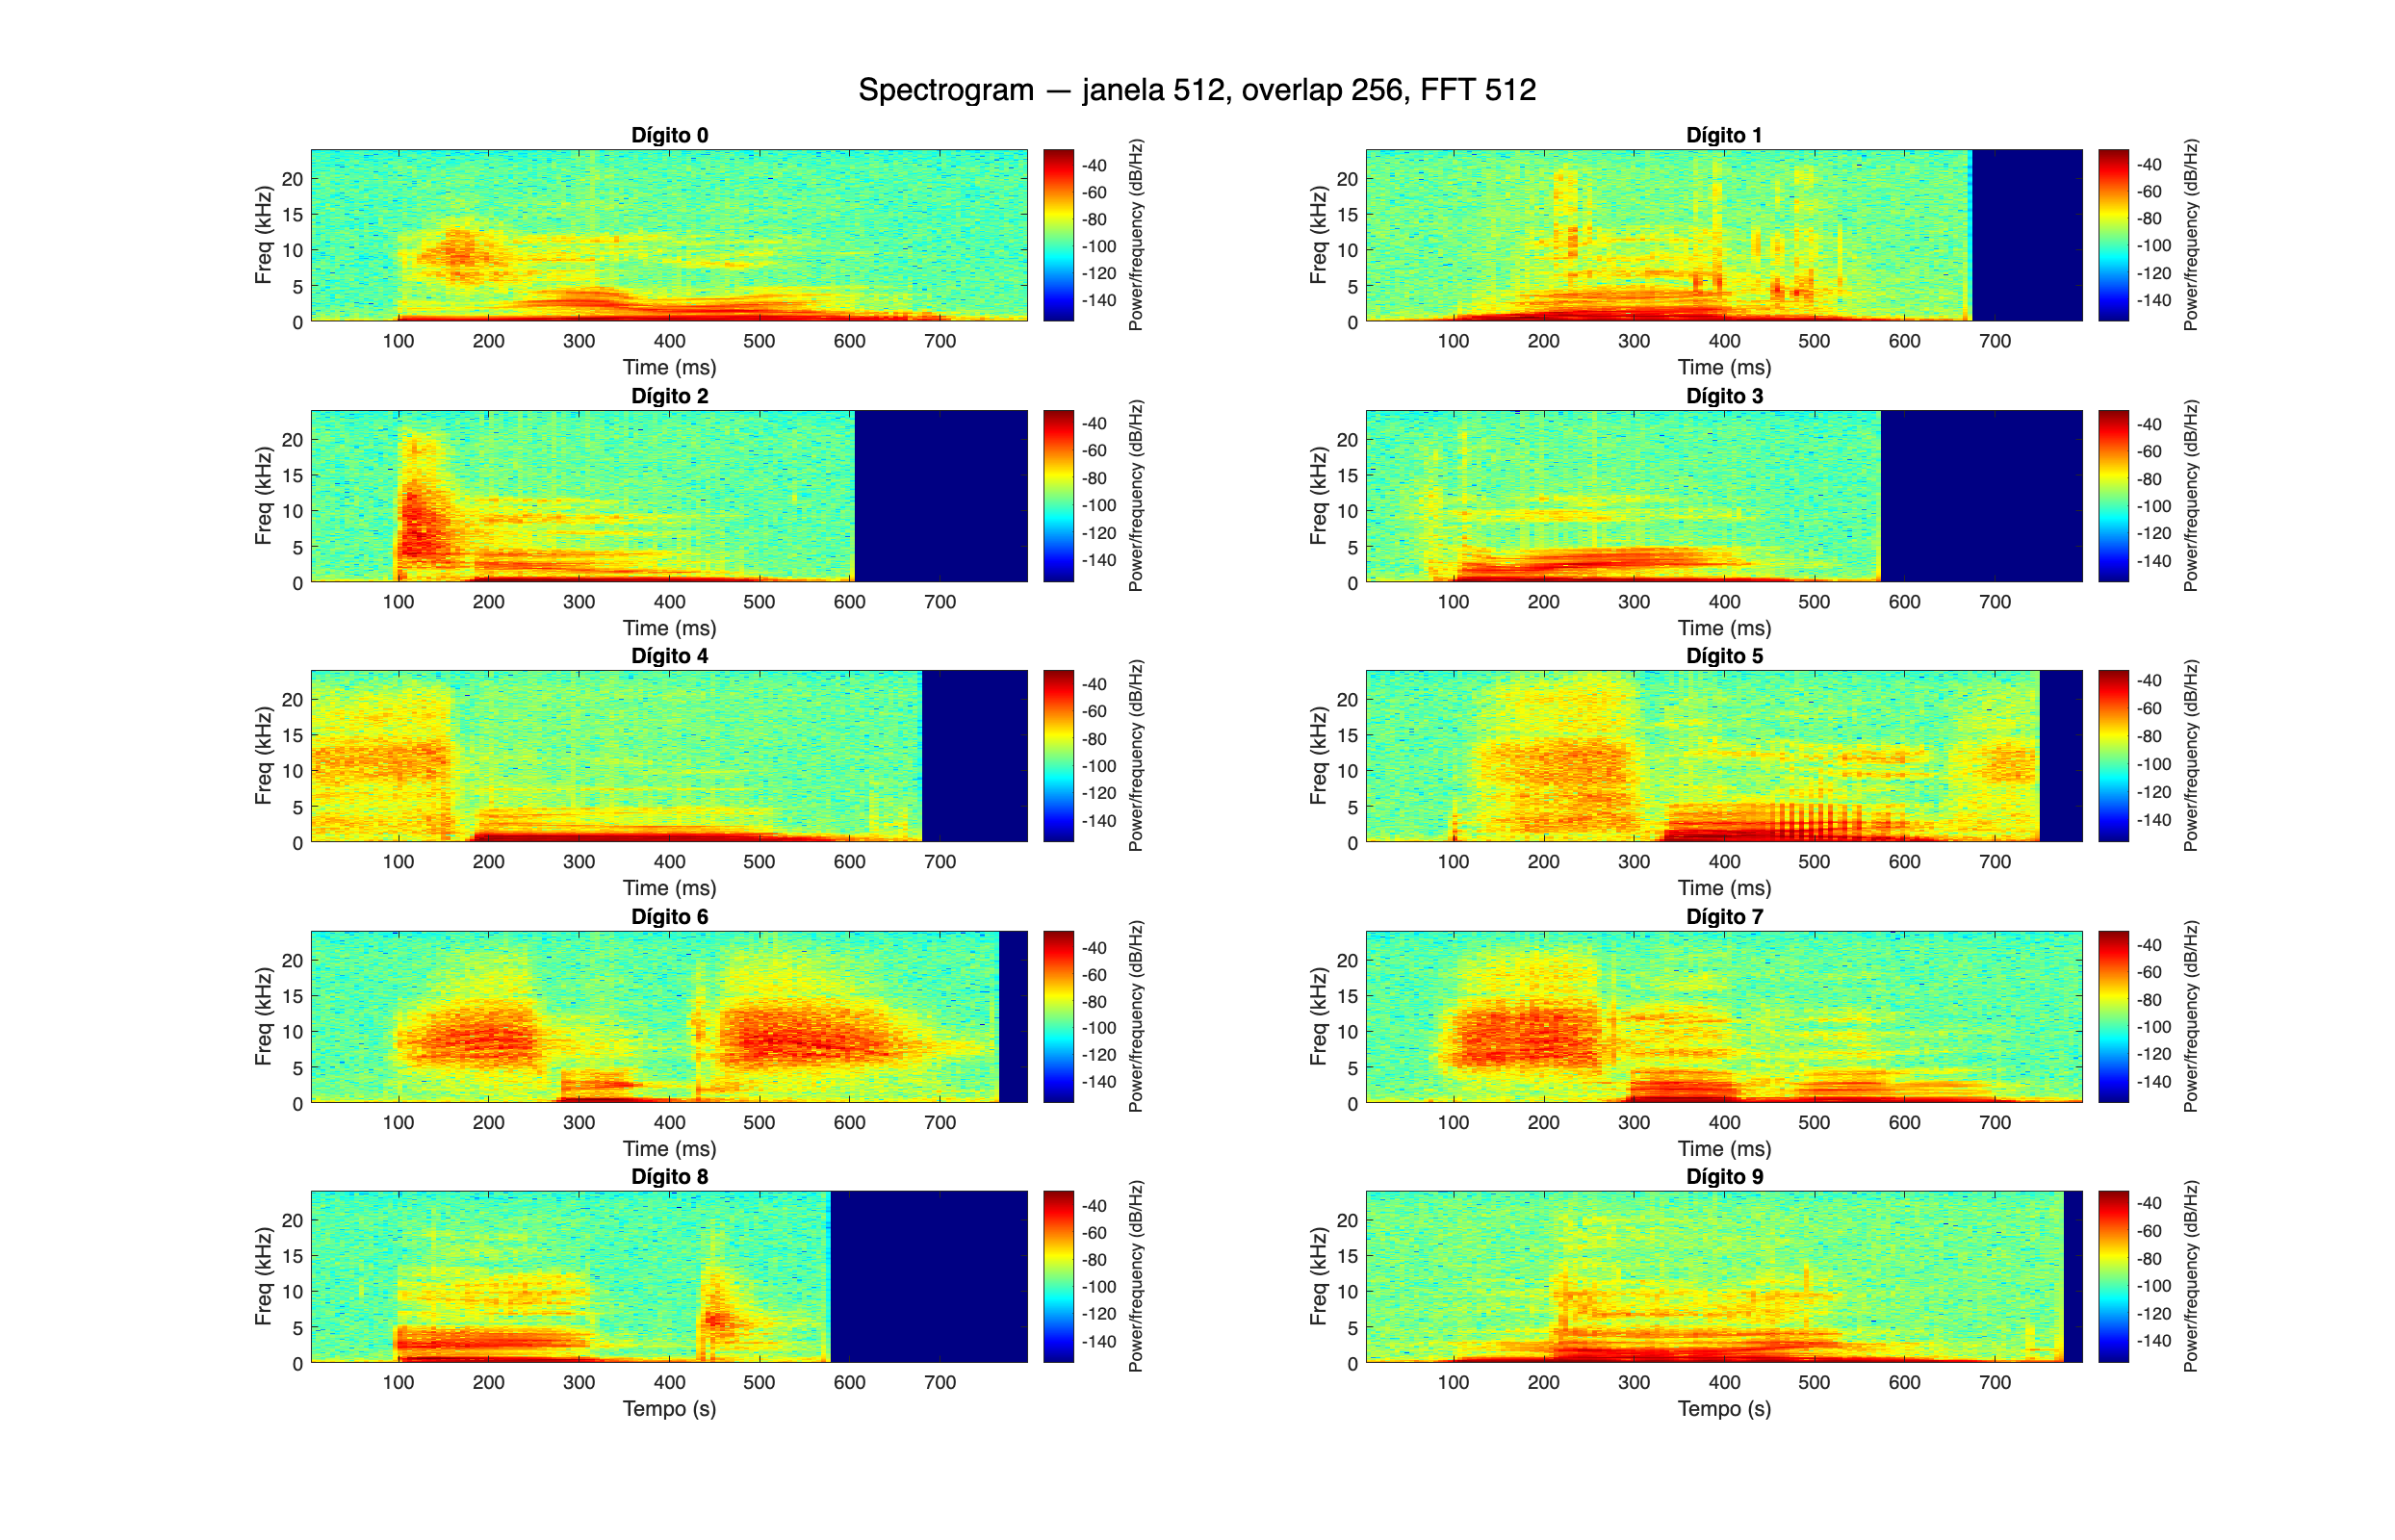

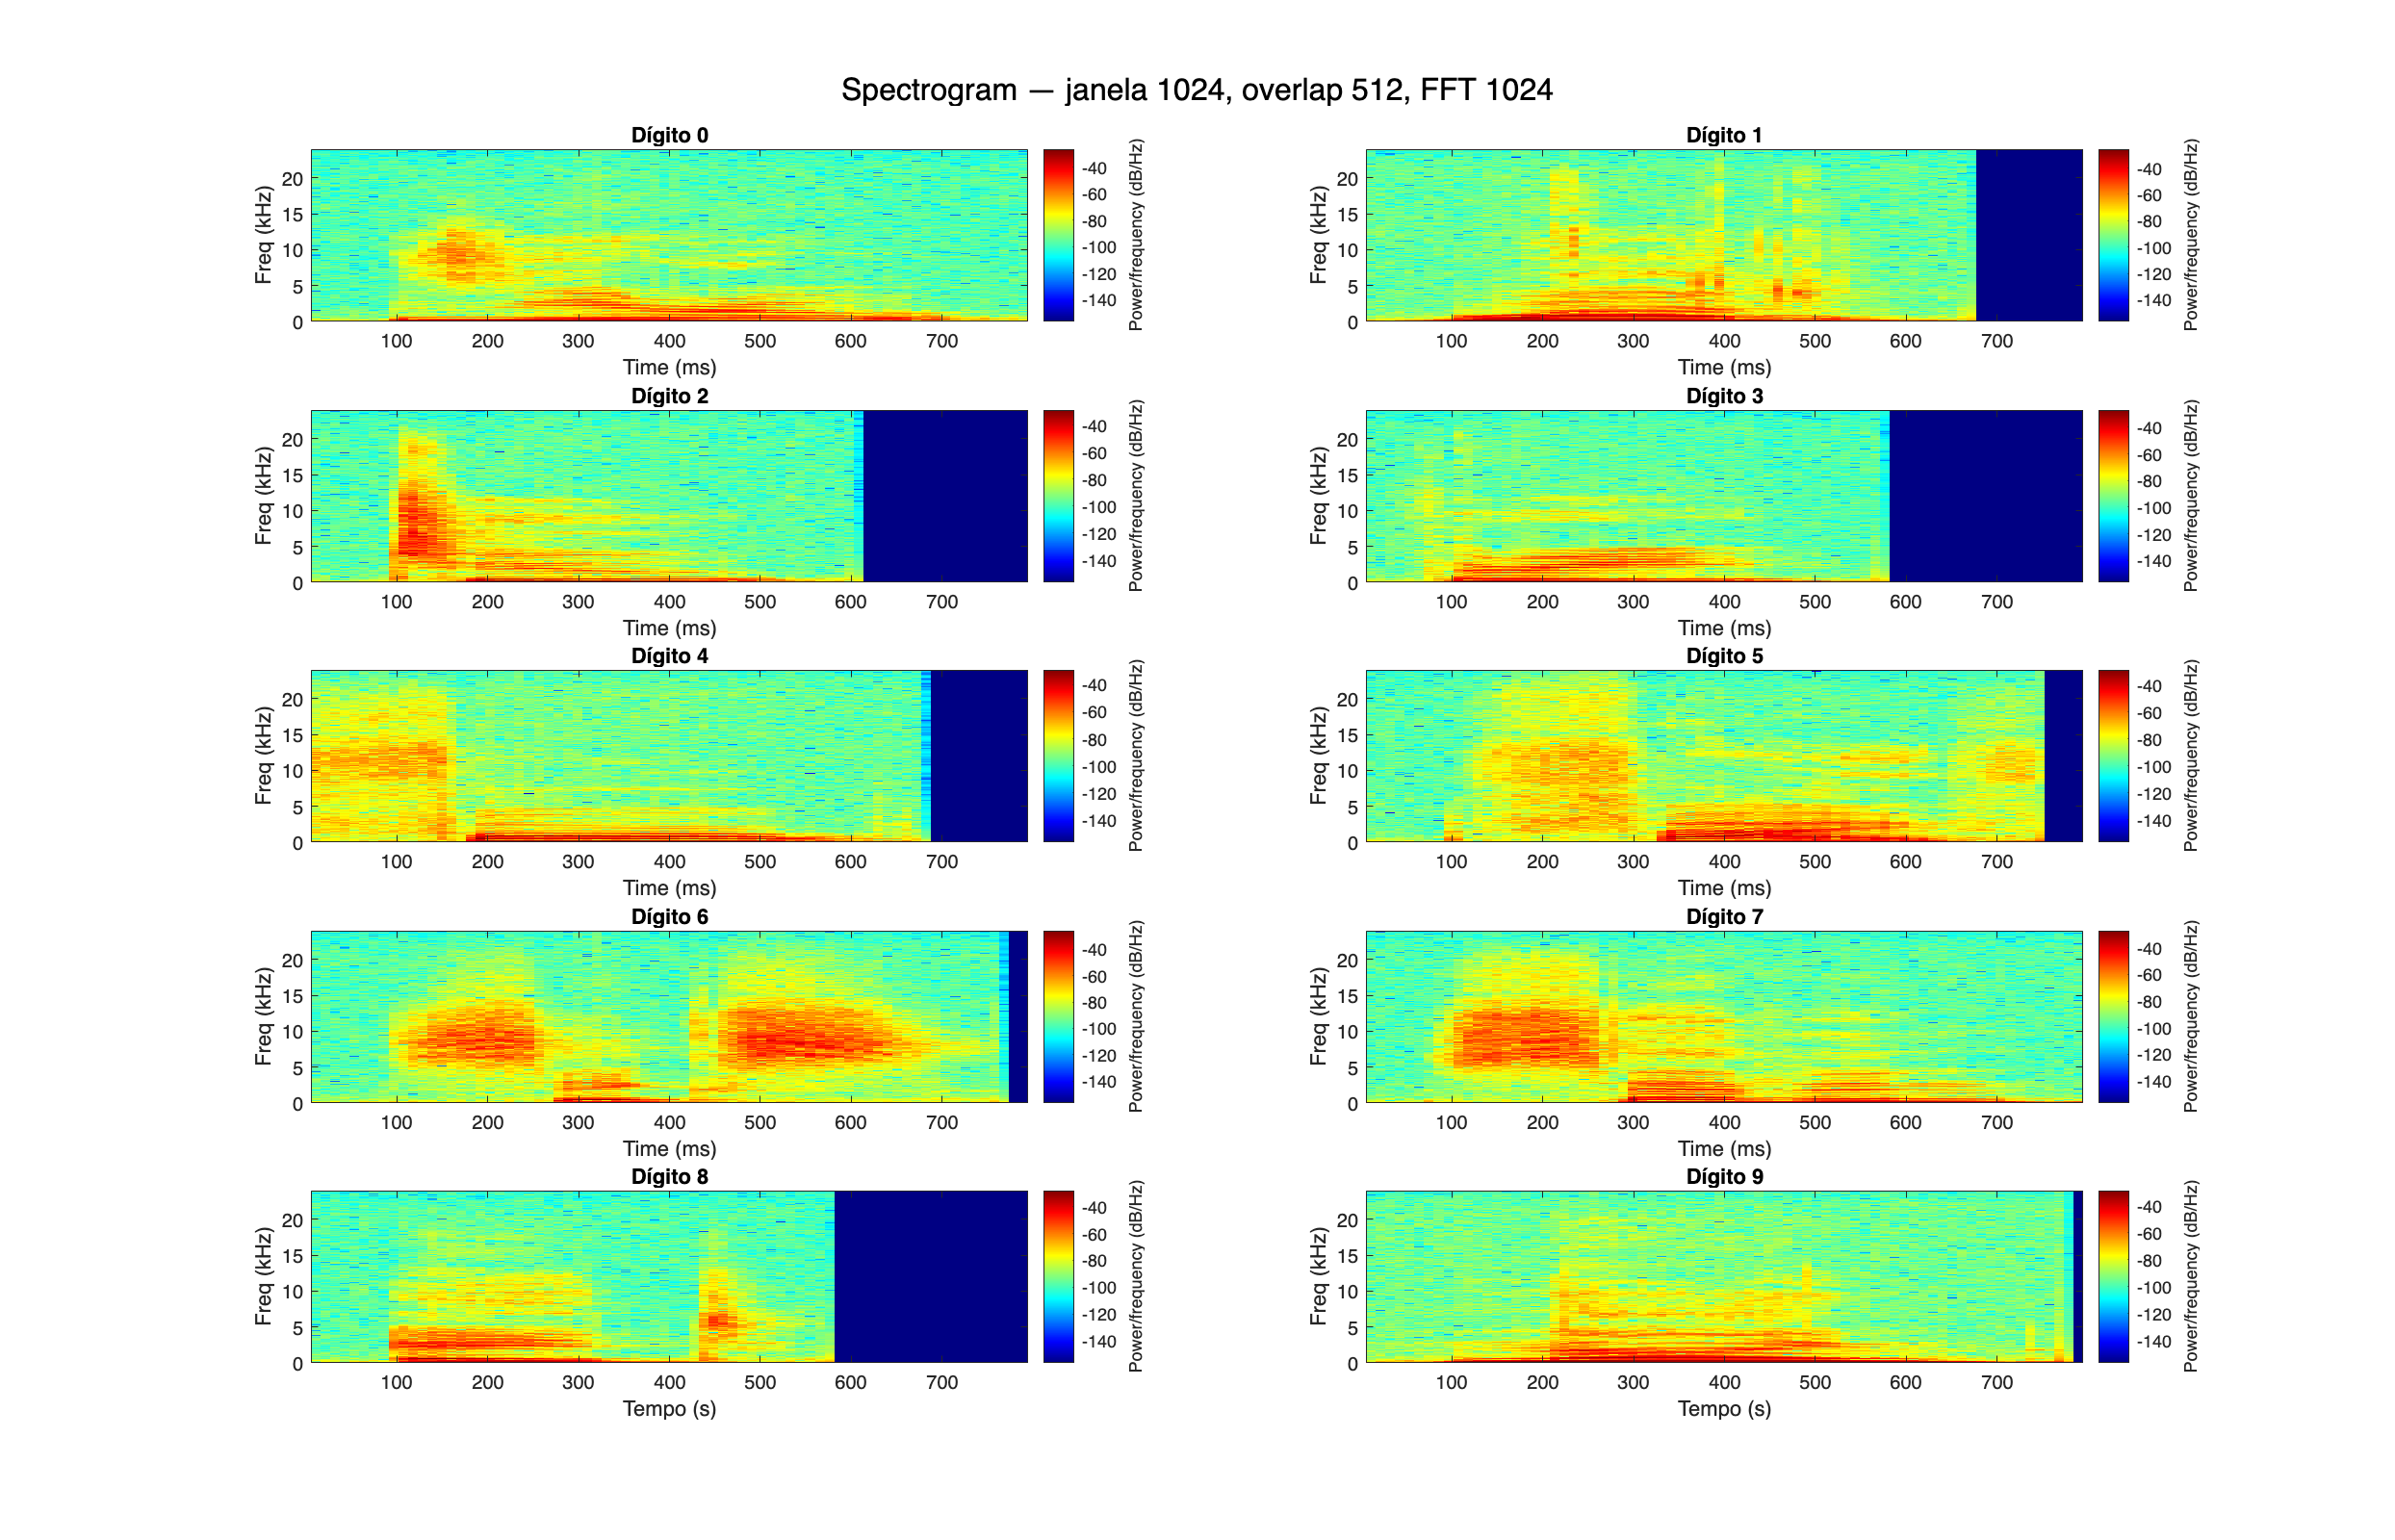

% Vamos testar três parametrizações diferentes de janela/overlap/nfft:
params = {
    struct('winLen', 256,  'overlap', 128, 'nfft', 256),
    struct('winLen', 512,  'overlap', 256, 'nfft', 512),
    struct('winLen', 1024, 'overlap', 512, 'nfft', 1024)
};

for p = 1:numel(params)
    winLen  = params{p}.winLen;
    overlap = params{p}.overlap;
    nfft    = params{p}.nfft;
    
    % número de linhas e colunas para 2 colunas
    nCols = 2;
    nRows = ceil(nDigits / nCols);
    
    % Cria uma figura “mais alta” para dar espaço aos subplots
    figure('Name', sprintf('STFT (win=%d, ovl=%d, nfft=%d)', winLen, overlap, nfft), ...
           'NumberTitle', 'off', ...
           'Units', 'pixels', ...
           'Position', [100, 100, 1400, 900]);  % largura x altura em pixels
    
    for k = 1:nDigits
        dig = digitosUnicos(k);
        idx = find(tabela.Digito == dig, 1);
        s   = tabela.Sinal_Processado{idx};
        fs  = tabela.Taxa_Amostragem(idx);
        
        % subplot em grade  nRows×2
        subplot(nRows, nCols, k);
        spectrogram(s, winLen, overlap, nfft, fs, 'yaxis');
        title(sprintf('Dígito %d', dig));
        ylabel('Freq (kHz)');
        if k > (nRows-1)*nCols
            xlabel('Tempo (s)');
        end
        colormap jet;
    end
    
    sgtitle(sprintf('Spectrogram — janela %d, overlap %d, FFT %d', winLen, overlap, nfft), 'FontSize', 16);
end

## Exercício 23: Extração de Características Tempo-Frequência

clear; clc;
load('AED1.mat','tabela');   % Tabela com Sinal_Processado e Taxa_Amostragem

n = height(tabela);

% Pré-aloca vetores de características
centroidMean   = zeros(n,1);
bandwidthMean  = zeros(n,1);
rolloffMean    = zeros(n,1);
fluxMean       = zeros(n,1);
flatnessMean   = zeros(n,1);

% Parâmetros STFT (escolhidos em Meta 4 como bons compromissos)
winLen  = 512;
overlap = 256;
nfft    = 512;

for i = 1:n
    s  = tabela.Sinal_Processado{i};
    fs = tabela.Taxa_Amostragem(i);
    
    % 1) calcula espectrograma
    [S, F, T] = spectrogram(s, winLen, overlap, nfft, fs);
    M = abs(S);
    
    % normaliza cada coluna (frame) para somar 1
    Mnorm = M ./ (sum(M,1) + eps);
    
    % 2) spectral centroid e bandwidth por frame
    centroid = sum(F .* Mnorm, 1);
    bw       = sqrt( sum(((F - centroid).^2) .* Mnorm, 1) );
    
    % 3) spectral rolloff (90%) por frame
    cumMag = cumsum(M,1);
    total  = cumMag(end,:);
    rolloff = zeros(1, size(M,2));
    thresh = 0.90 * total;
    for t = 1:numel(thresh)
        idx = find(cumMag(:,t) >= thresh(t),1);
        rolloff(t) = F(idx);
    end
    
    % 4) spectral flux (diferença entre frames sucessivos)
    Mnorm2 = Mnorm ./ max(Mnorm,[],1);  % reforça comparação
    flux = [0, sum((diff(Mnorm2,1,2)).^2, 1)];
    
    % 5) spectral flatness por frame = GM/AM
    gm = exp( mean(log(M + eps),1) );
    am = mean(M + eps,1);
    flatness = gm ./ am;
    
    % estatísticas (média ao longo do tempo)
    centroidMean(i)  = mean(centroid);
    bandwidthMean(i) = mean(bw);
    rolloffMean(i)   = mean(rolloff);
    fluxMean(i)      = mean(flux);
    flatnessMean(i)  = mean(flatness);
end

% Atualiza tabela
tabela.Centroid_Mean       = centroidMean;
tabela.Bandwidth_Mean      = bandwidthMean;
tabela.Rolloff90_Mean      = rolloffMean;
tabela.Flux_Mean           = fluxMean;
tabela.Flatness_Mean       = flatnessMean;

% Salva a tabela com as novas features
save('AED1.mat','tabela');
disp('Ex23 concluído: tabela atualizada com 5 features TF.');

Ex23 concluído: tabela atualizada com 5 features TF.


disp(tabela(:, end-4:end));  % mostra só as 5 novas colunas

    Centroid_Mean    Bandwidth_Mean    Rolloff90_Mean    Flux_Mean    Flatness_Mean
    _____________    ______________    ______________    _________    _____________

       2021.8            3997.5              6061        0.080311        0.13708   
       843.63            2043.5            1559.8             NaN        0.36125   
         2935            3888.2            6612.2         0.40348        0.16214   
       2281.2            3782.5            5779.8             NaN        0.19309   
       760.28            1804.6            1659.8             NaN        0.49063   
       1955.1            3569.9            5107.8             NaN        0.19567   
       2463.6            3972.1            6429.7         0.12179        0.15045   
       1910.9            3991.3            5258.2        0.049888        

## Exercício 24: Visualização e Seleção das Melhores Características Tempo–Frequência

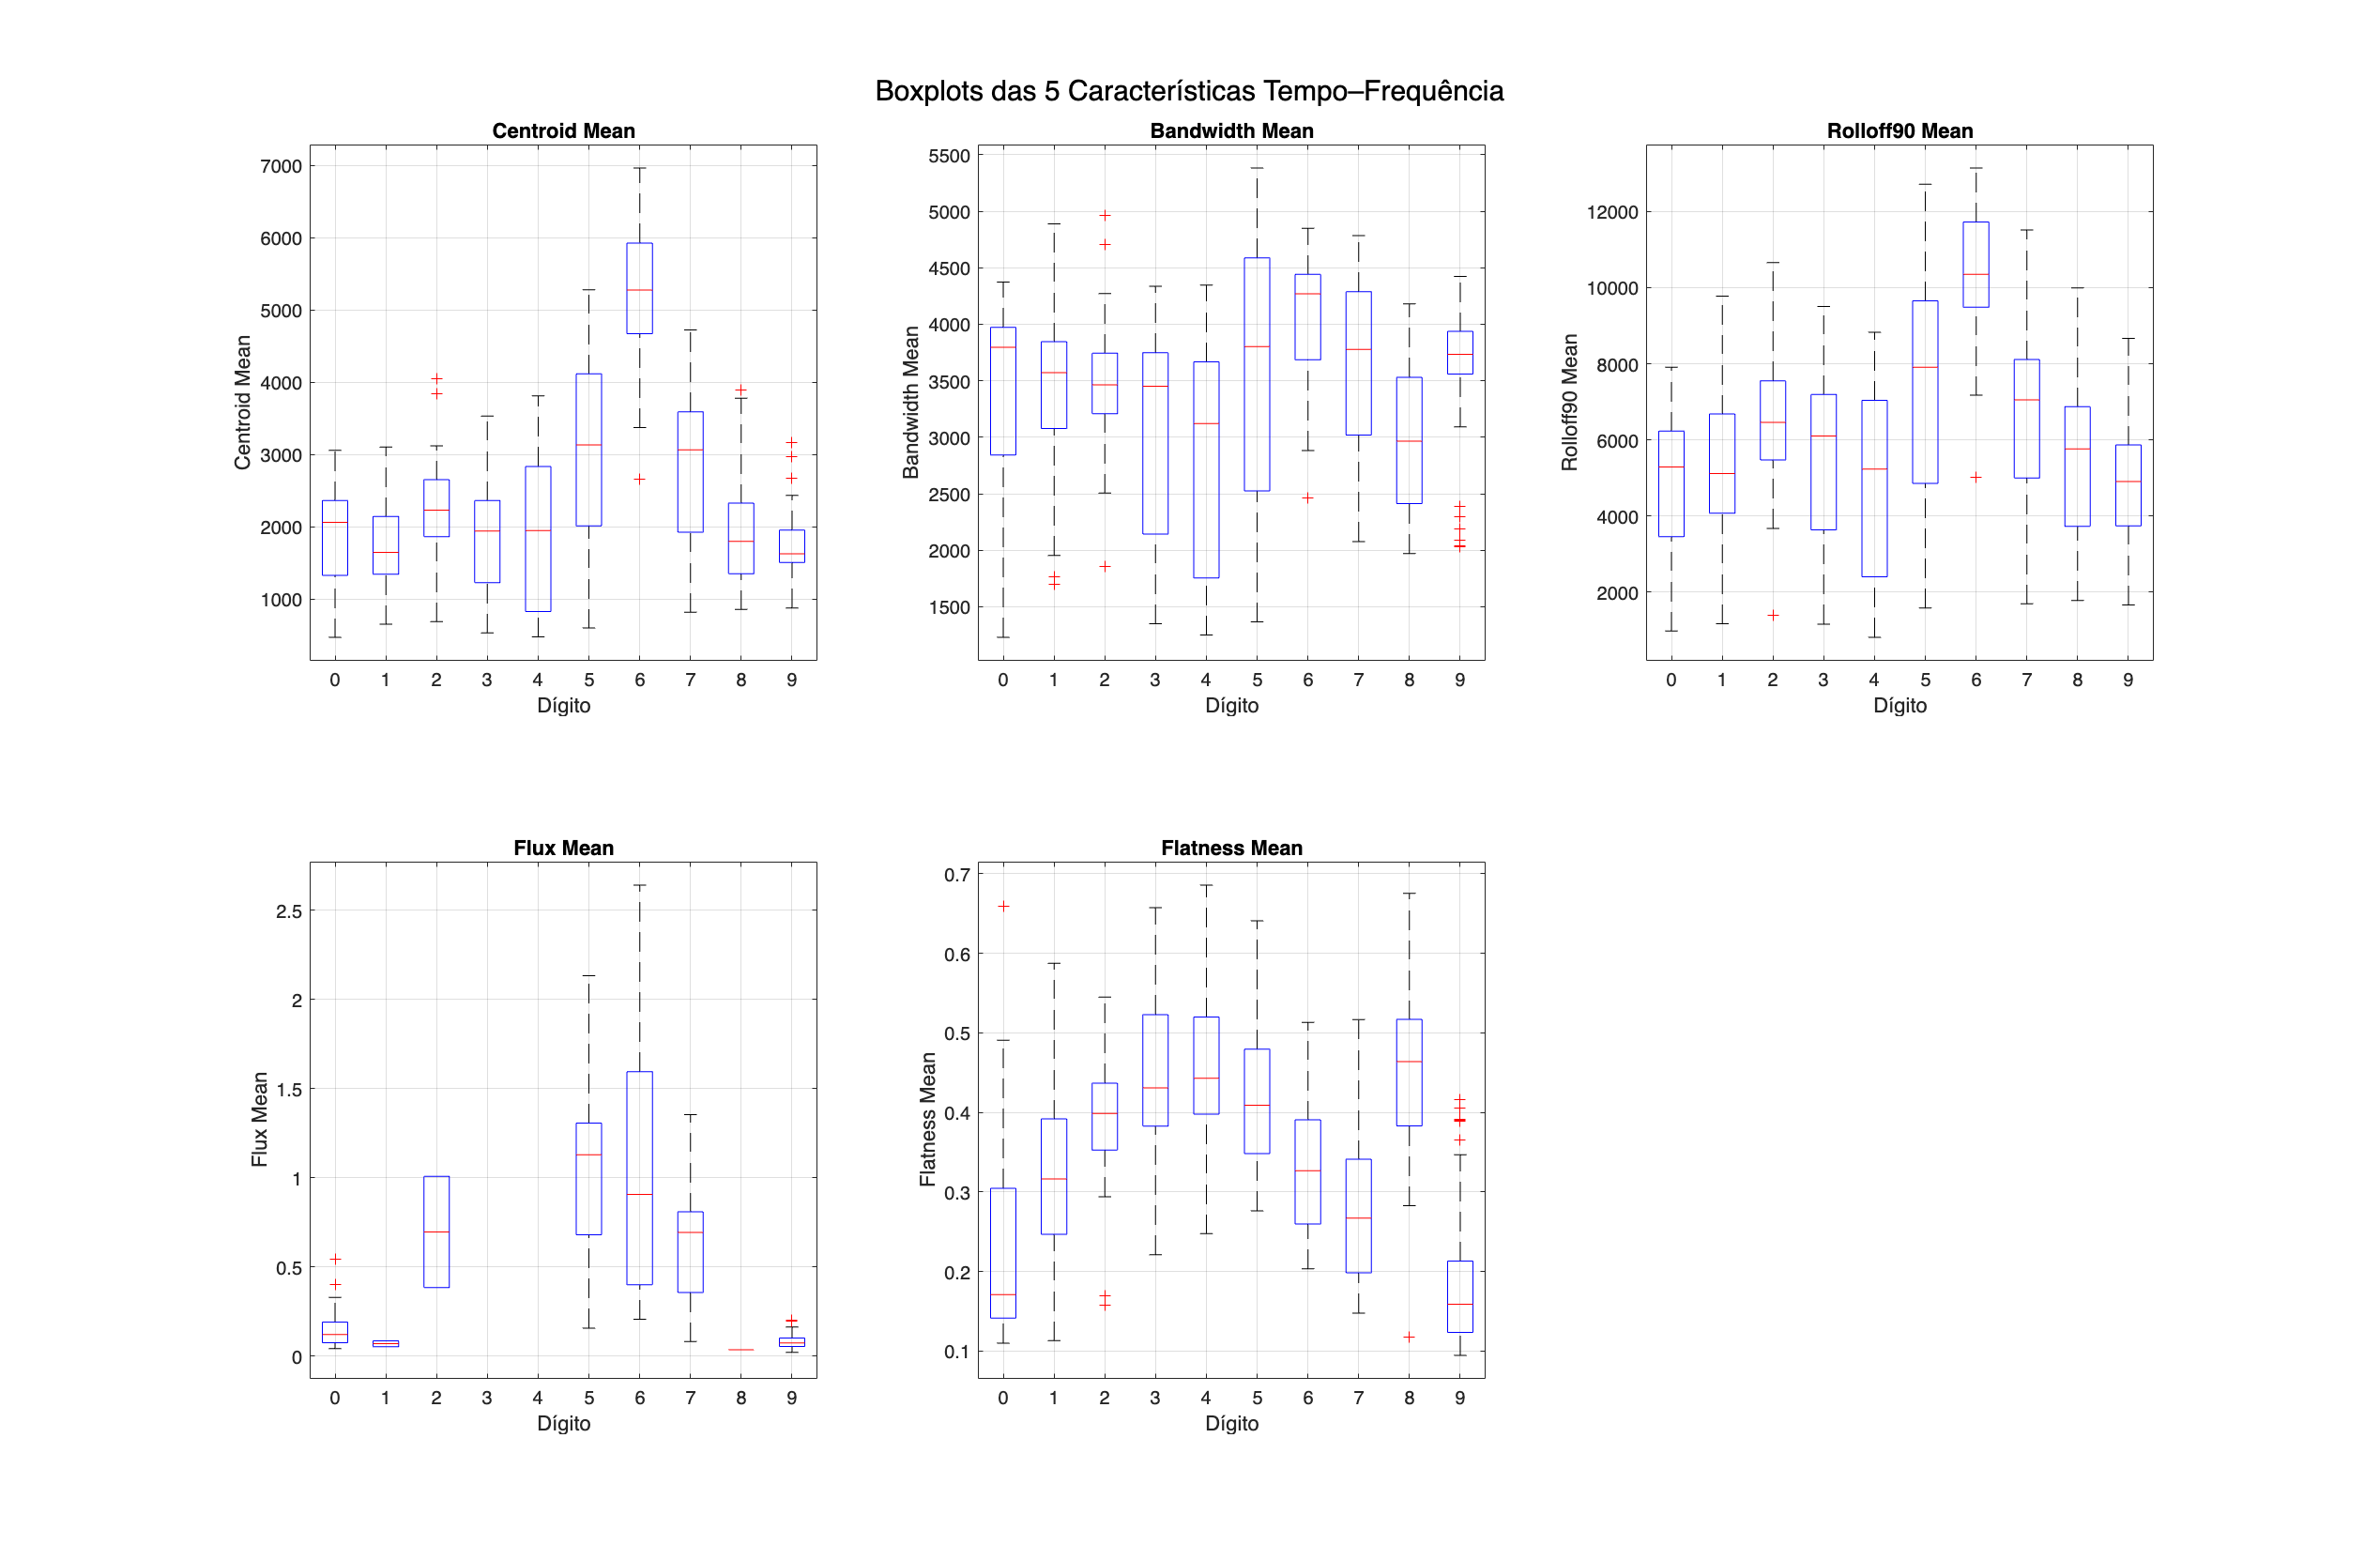

clear; clc; close all;
load('AED1.mat','tabela');   % Carrega a tabela com as 5 features TF

digitosUnicos = unique(tabela.Digito);

% Lista das características TF
features = { ...
    'Centroid_Mean', ...
    'Bandwidth_Mean', ...
    'Rolloff90_Mean', ...
    'Flux_Mean', ...
    'Flatness_Mean' ...
};

nFeat = numel(features);

%% 1) Boxplots de cada feature por dígito
figure('Name','Boxplots das Features TF','NumberTitle','off','Units','normalized','OuterPosition',[0 0 1 1]);
for i = 1:nFeat
    subplot(2,3,i);
    boxplot(tabela.(features{i}), tabela.Digito);
    xlabel('Dígito'); ylabel(strrep(features{i},'_',' '));
    title(strrep(features{i},'_',' '));
    grid on;
end
sgtitle('Boxplots das 5 Características Tempo–Frequência');

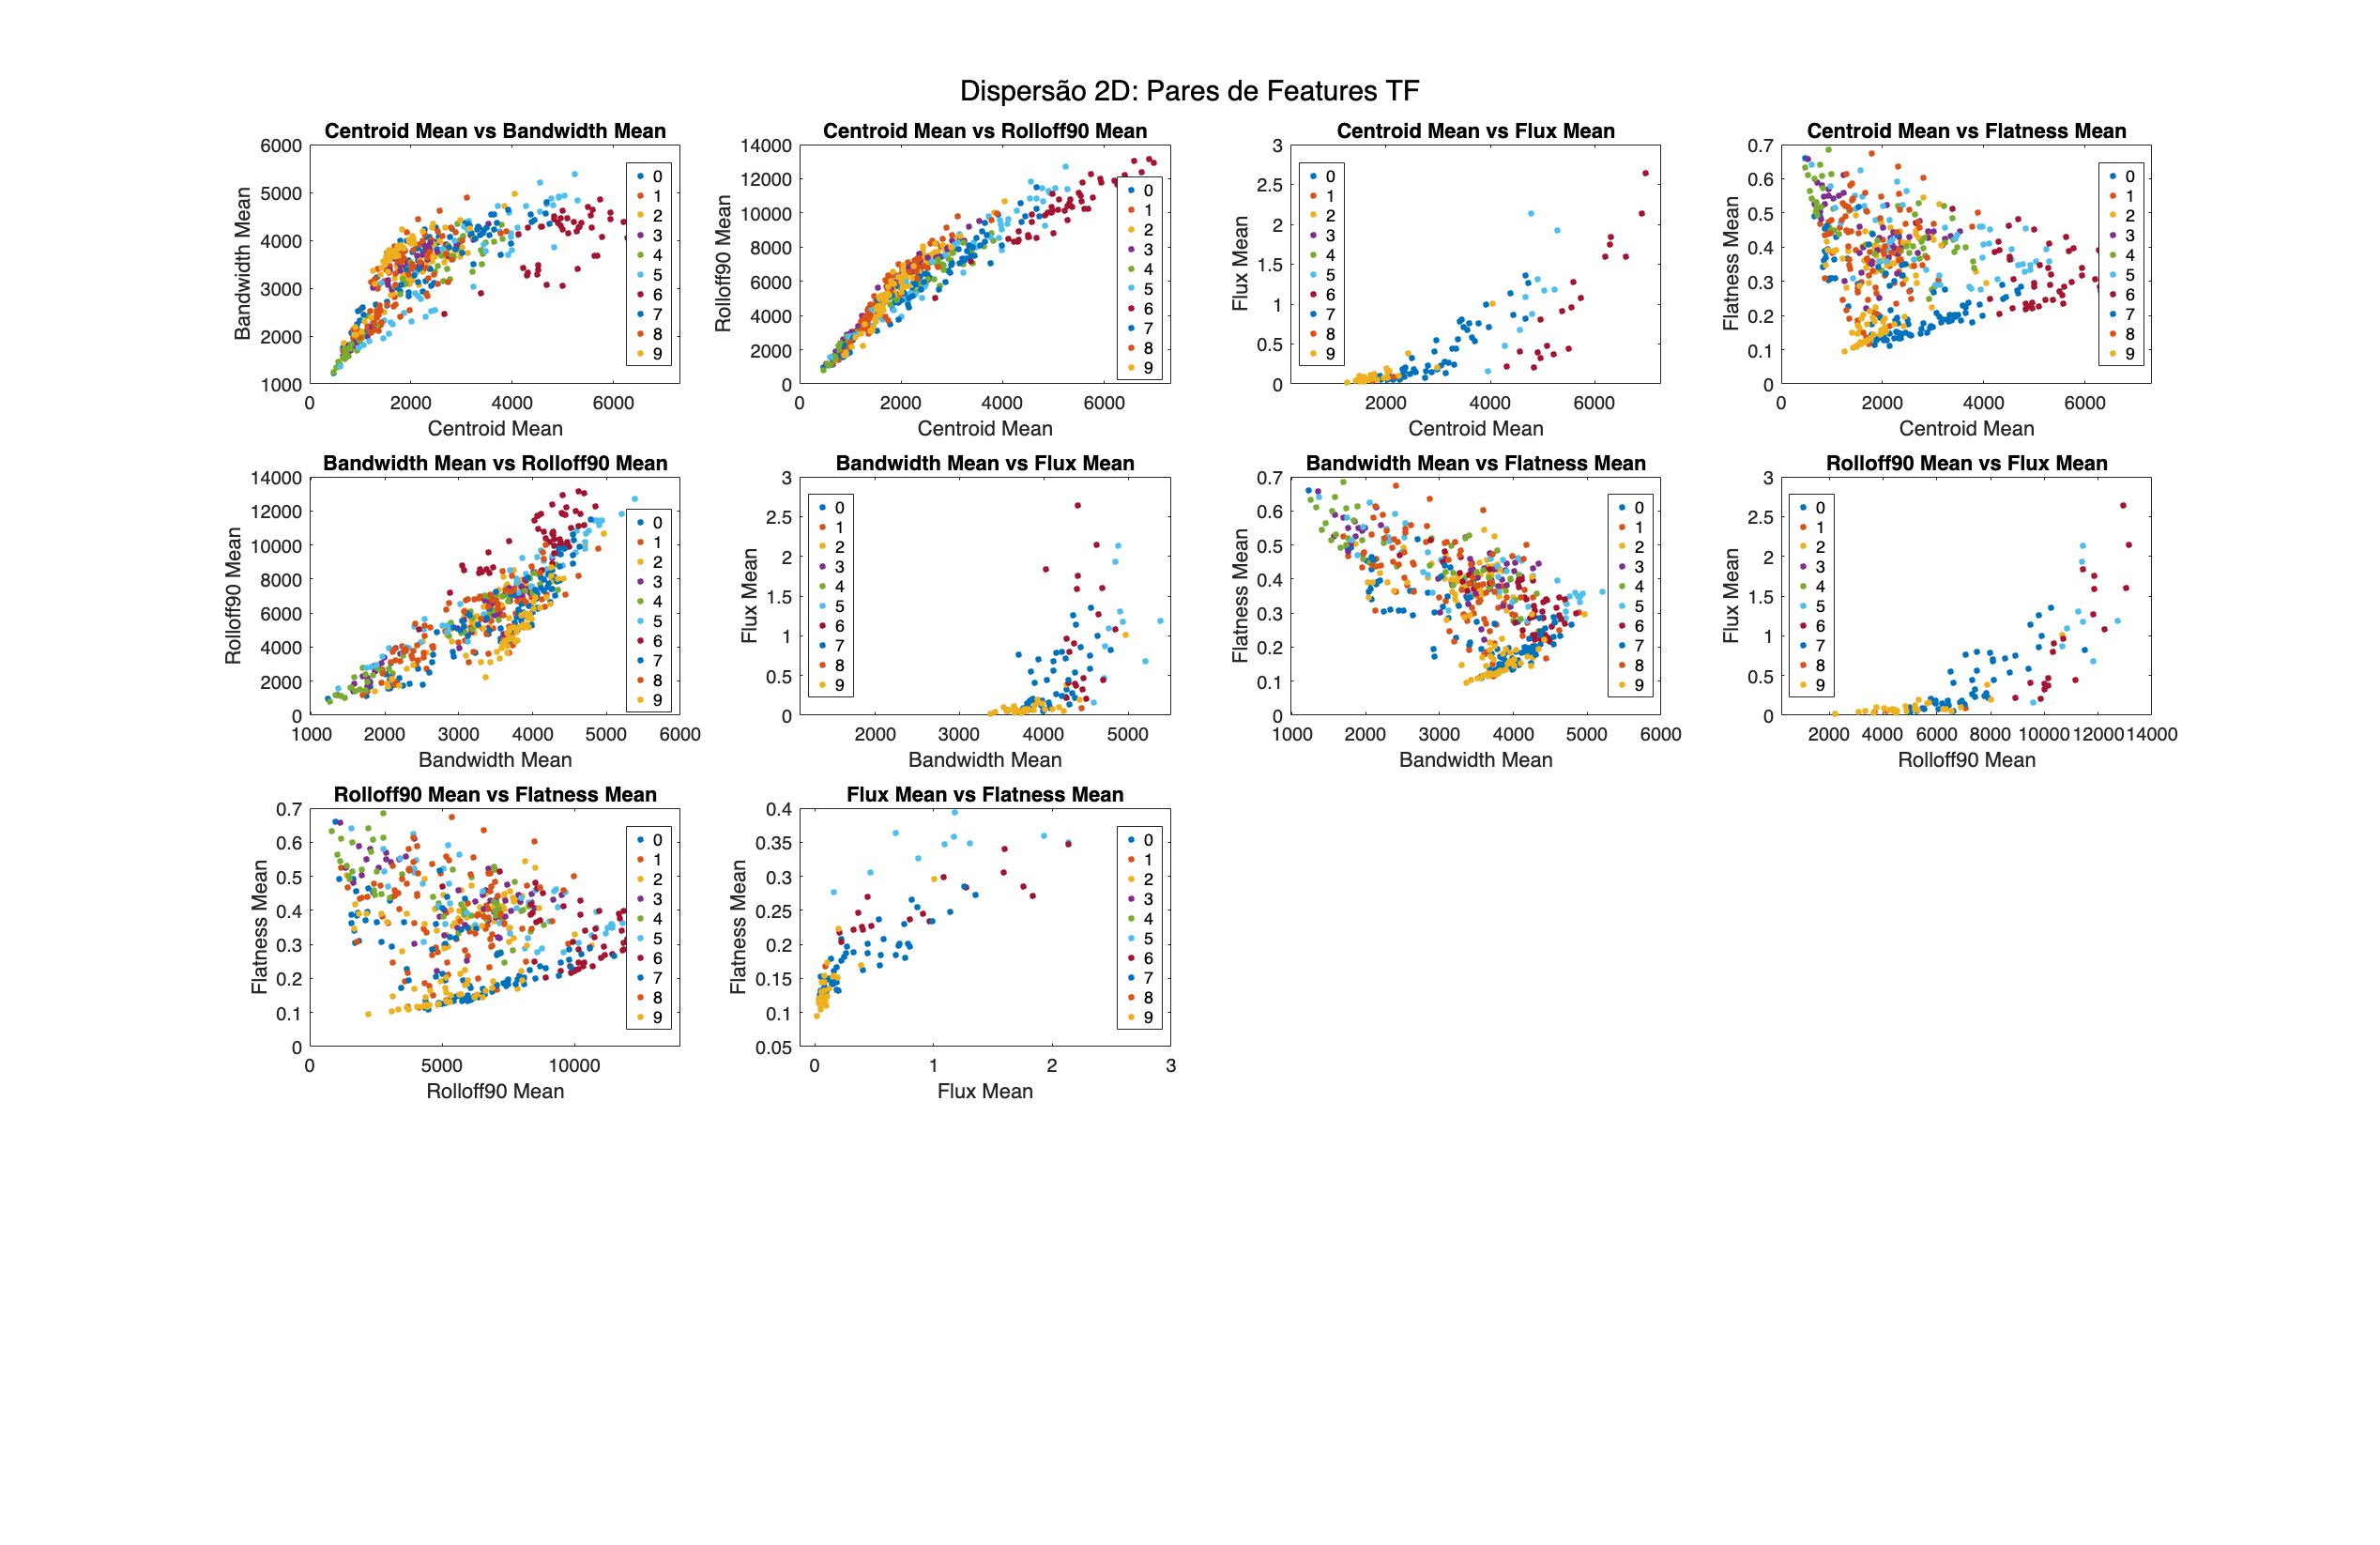


%% 2) Gráficos de Dispersão 2D: todas as combinações pares
figure('Name','Scatter 2D das Combinações de Features TF','NumberTitle','off','Units','normalized','OuterPosition',[0 0 1 1]);
plotIdx = 1;
for i = 1:nFeat-1
    for j = i+1:nFeat
        subplot(nFeat-1, nFeat-1, plotIdx);
        gscatter(tabela.(features{i}), tabela.(features{j}), tabela.Digito, [], '.', 10);
        xlabel(strrep(features{i},'_',' '));
        ylabel(strrep(features{j},'_',' '));
        title(sprintf('%s vs %s', strrep(features{i},'_',' '), strrep(features{j},'_',' ')));
        plotIdx = plotIdx + 1;
    end
end
sgtitle('Dispersão 2D: Pares de Features TF');

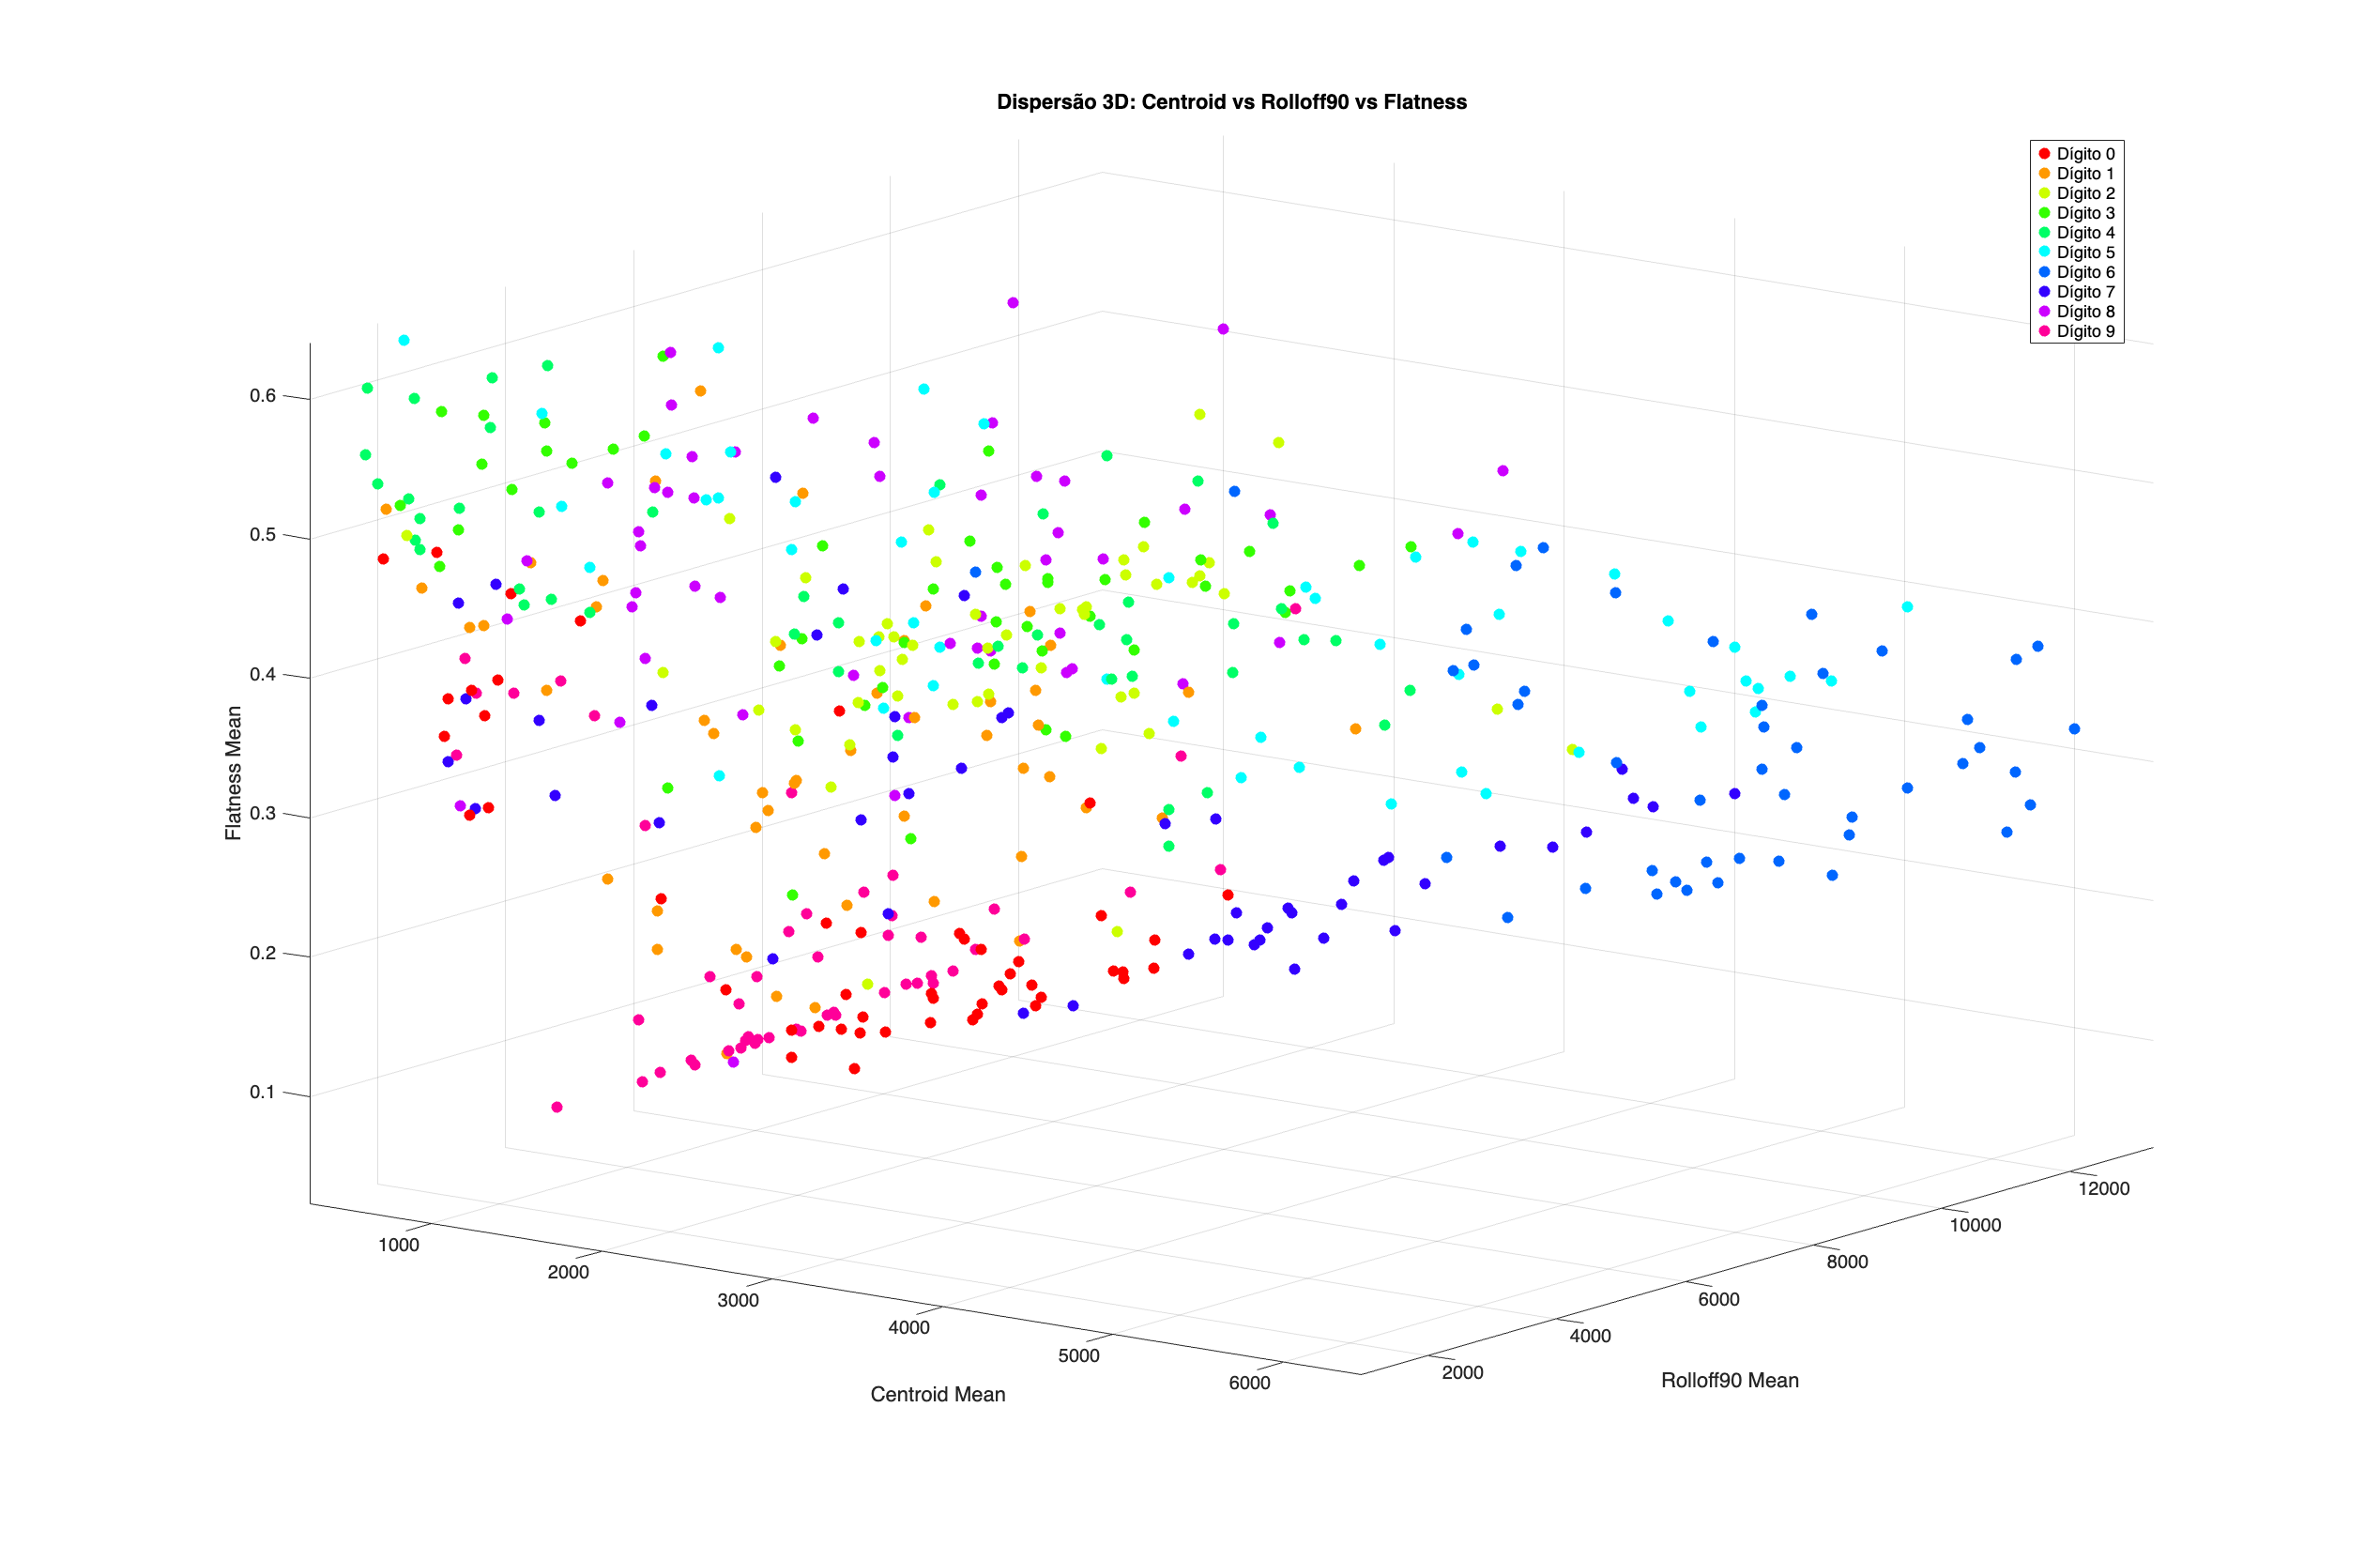


%% 3) Dispersão 3D para as três melhores candidates
% Com base na separação visual dos plots acima, escolhemos:
feat1 = 'Centroid_Mean';
feat2 = 'Rolloff90_Mean';
feat3 = 'Flatness_Mean';

figure('Name','Scatter 3D das 3 Features Selecionadas','NumberTitle','off','Units','normalized','OuterPosition',[0 0 1 1]);
colors = hsv(numel(digitosUnicos));
hold on;
for k = 1:numel(digitosUnicos)
    d = digitosUnicos(k);
    idx = tabela.Digito == d;
    scatter3( ...
        tabela.(feat1)(idx), ...
        tabela.(feat2)(idx), ...
        tabela.(feat3)(idx), ...
        36, colors(k,:), 'filled' ...
    );
end
hold off;
xlabel(strrep(feat1,'_',' '));
ylabel(strrep(feat2,'_',' '));
zlabel(strrep(feat3,'_',' '));
title('Dispersão 3D: Centroid vs Rolloff90 vs Flatness');
legend(arrayfun(@(d) sprintf('Dígito %d',d), digitosUnicos, 'UniformOutput',false), 'Location','best');
grid on;
view(45,20);


%% 4) Indicação das Três Características Escolhidas
fprintf('\nAs três características selecionadas que melhor discriminam os dígitos foram:\n');


As três características selecionadas que melhor discriminam os dígitos foram:


fprintf('  1) Centroid_Mean (centroide espectral médio)\n');

  1) Centroid_Mean (centroide espectral médio)


fprintf('  2) Rolloff90_Mean (rolloff a 90%% médio)\n');

  2) Rolloff90_Mean (rolloff a 90% médio)


fprintf('  3) Flatness_Mean (flatness espectral média)\n\n');

  3) Flatness_Mean (flatness espectral média)



## Exercício 25: Análise via Transformada Discreta de Wavelet (DWT)

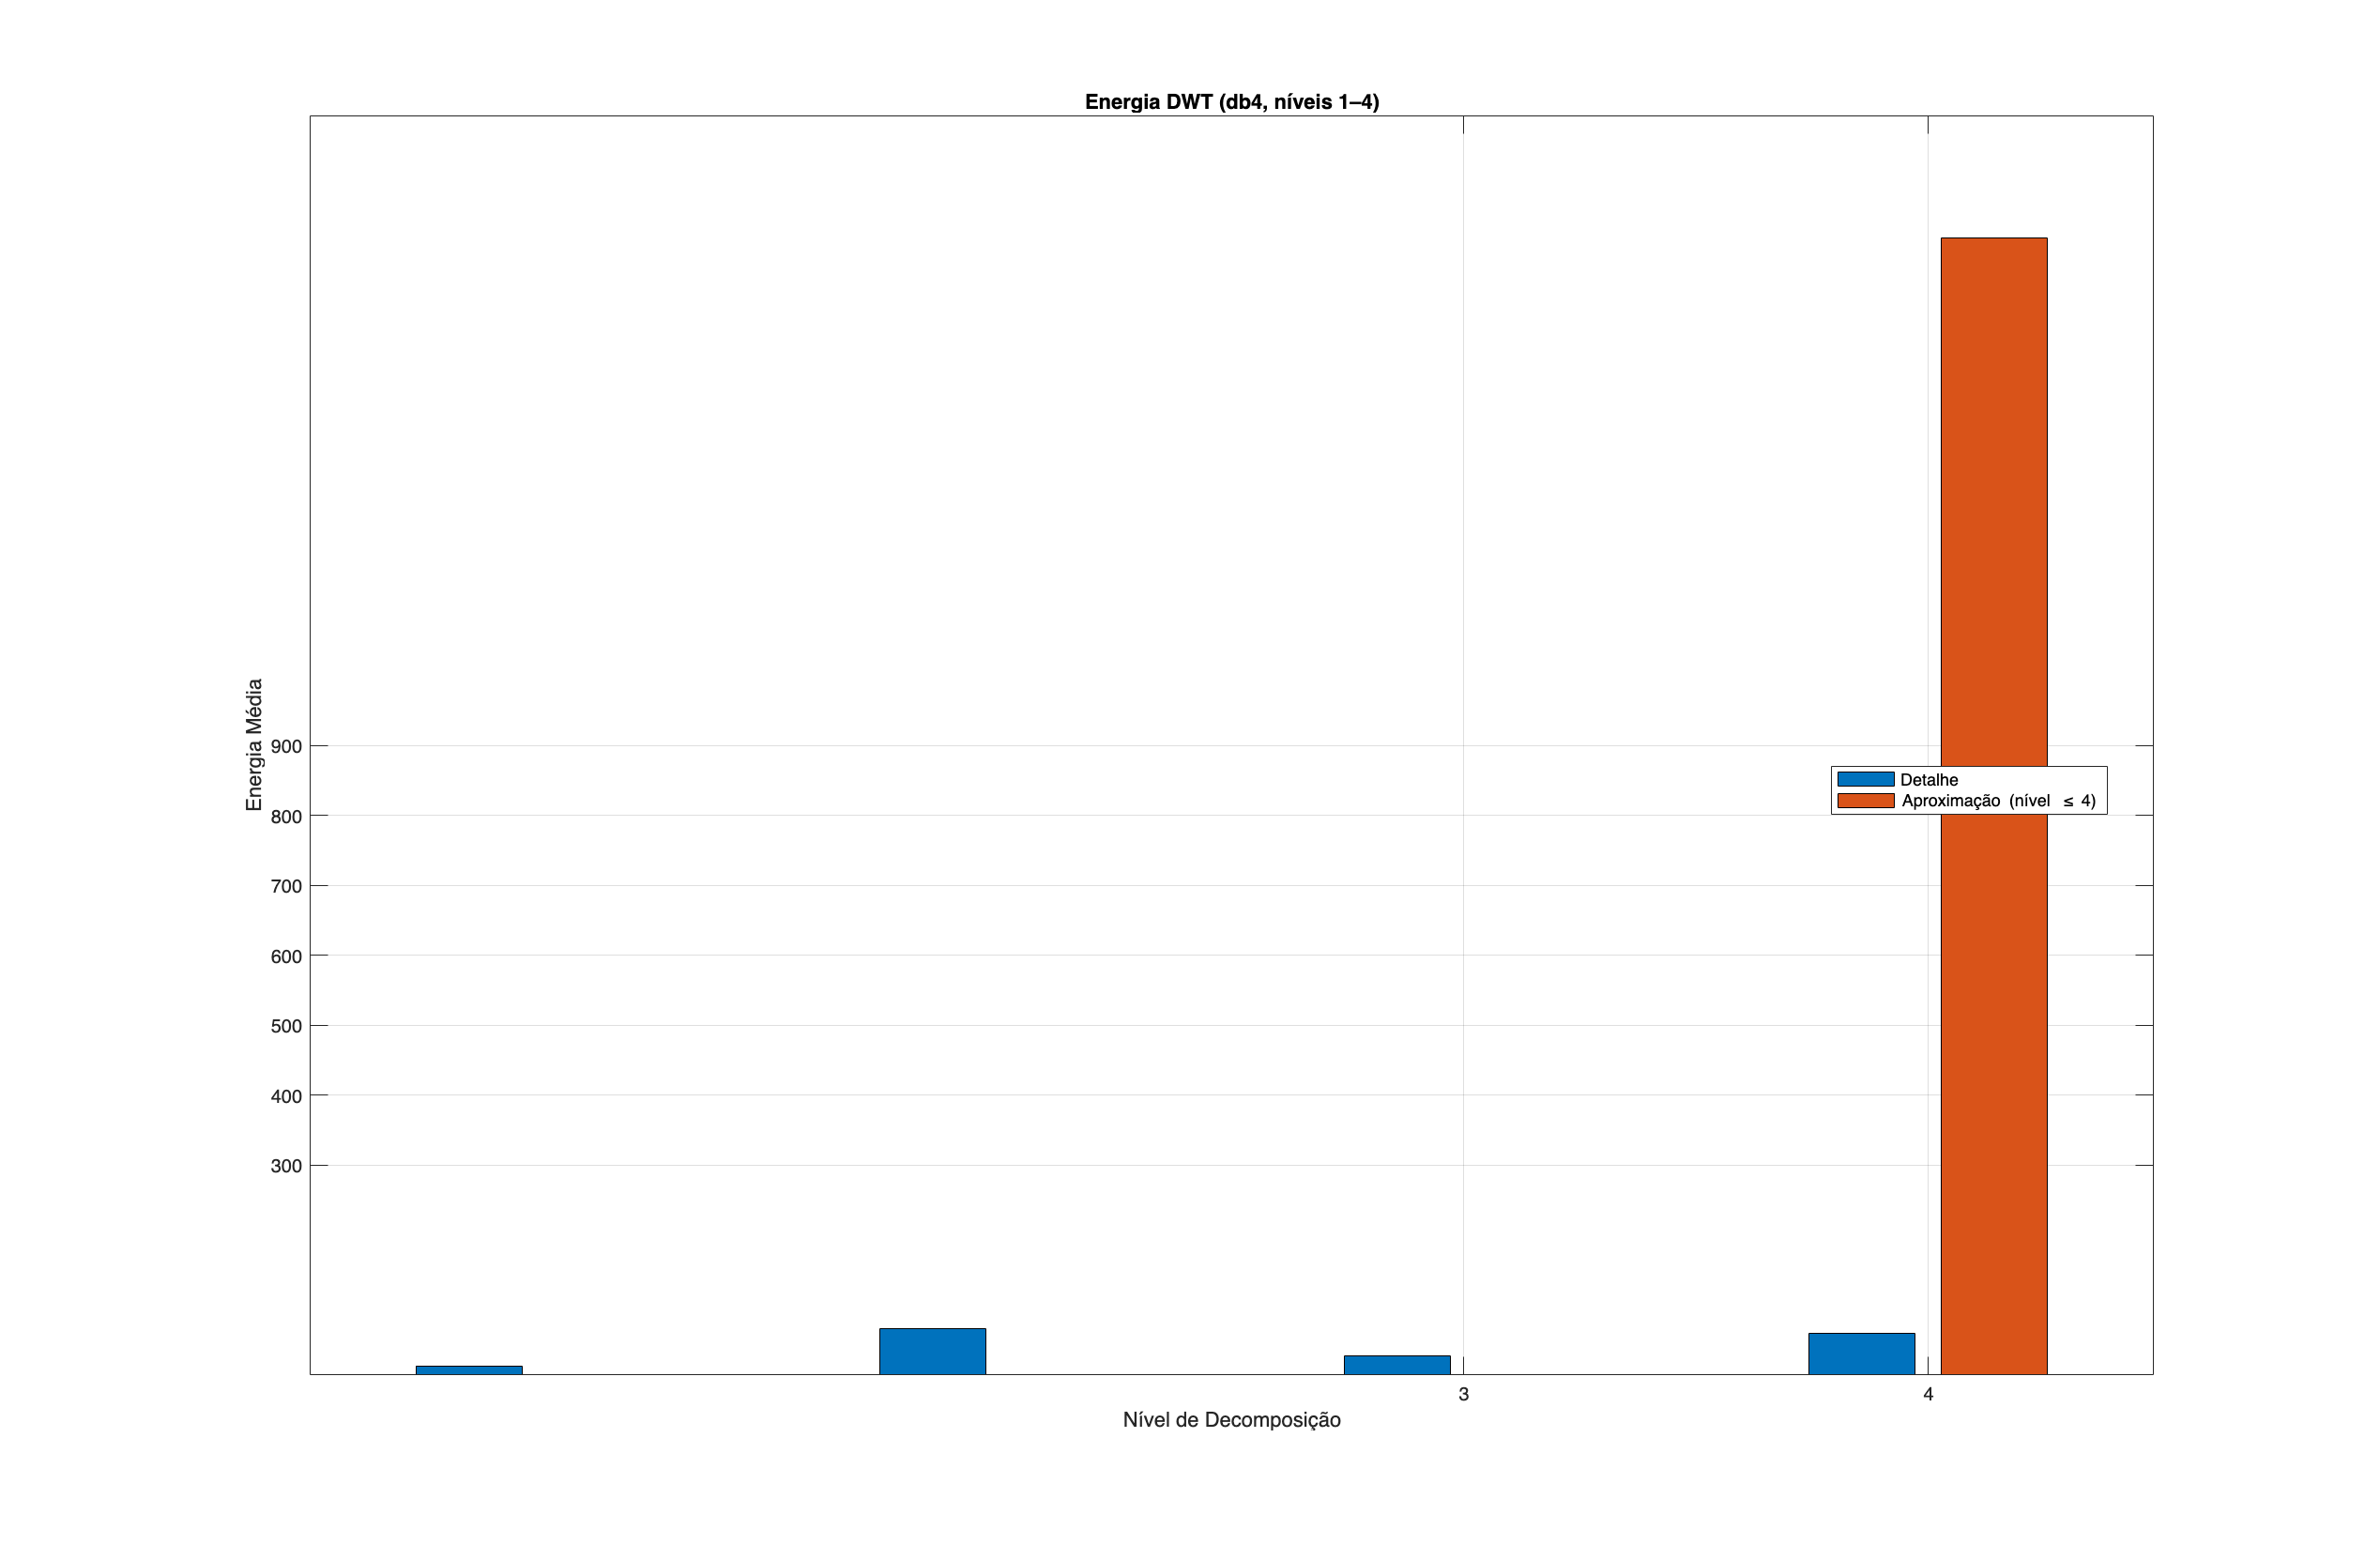

% - Aplica DWT a cada sinal processado para extrair coeficientes de aproximação e detalhe
% - Calcula as energias desses coeficientes
% - Plota resultados comparáveis aos da Figura 3 (energia por nível)
% - Compara qualitativamente STFT × DWT

clear; clc; close all;
load('AED1.mat','tabela');   % espera-se que 'tabela' tenha Sinal_Processado e Taxa_Amostragem

% Parâmetros DWT
waveletName = 'db4';   % Daubechies ordem 4 (boa compensação tempo-freq)
decompLevel = 4;       % Nível de decomposição

n = height(tabela);
energiaAprox = zeros(n, decompLevel);
energiaDet   = zeros(n, decompLevel);

for i = 1:n
    s = tabela.Sinal_Processado{i};
    
    % Computa DWT multínivel
    [C, L] = wavedec(s, decompLevel, waveletName);
    
    % Para cada nível, extrai coeficientes de detalhe e aproximação
    % L estrutura: [lenA4, lenD4, lenD3, lenD2, lenD1]
    for lev = 1:decompLevel
        % detalhe de nível `lev`
        d = detcoef(C, L, lev);
        energiaDet(i, lev) = sum(d.^2);
    end
    % aproximação no nível máximo
    a = appcoef(C, L, waveletName, decompLevel);
    energiaAprox(i, decompLevel) = sum(a.^2);
end

% 1) Energia Média por Nível (aprox. e detalhes)
energAproxMean = mean(energiaAprox, 1);
energDetMean   = mean(energiaDet,   1);

levels = 1:decompLevel;

figure('Name','Energia da DWT por Nível','NumberTitle','off','Units','normalized','OuterPosition',[0 0 1 1]);
bar(levels, [energDetMean; energAproxMean]', 'grouped');
xlabel('Nível de Decomposição');
ylabel('Energia Média');
legend('Detalhe','Aproximação (nível \leq 4)','Location','best');
title(sprintf('Energia DWT (%s, níveis 1–%d)', waveletName, decompLevel));
grid on;

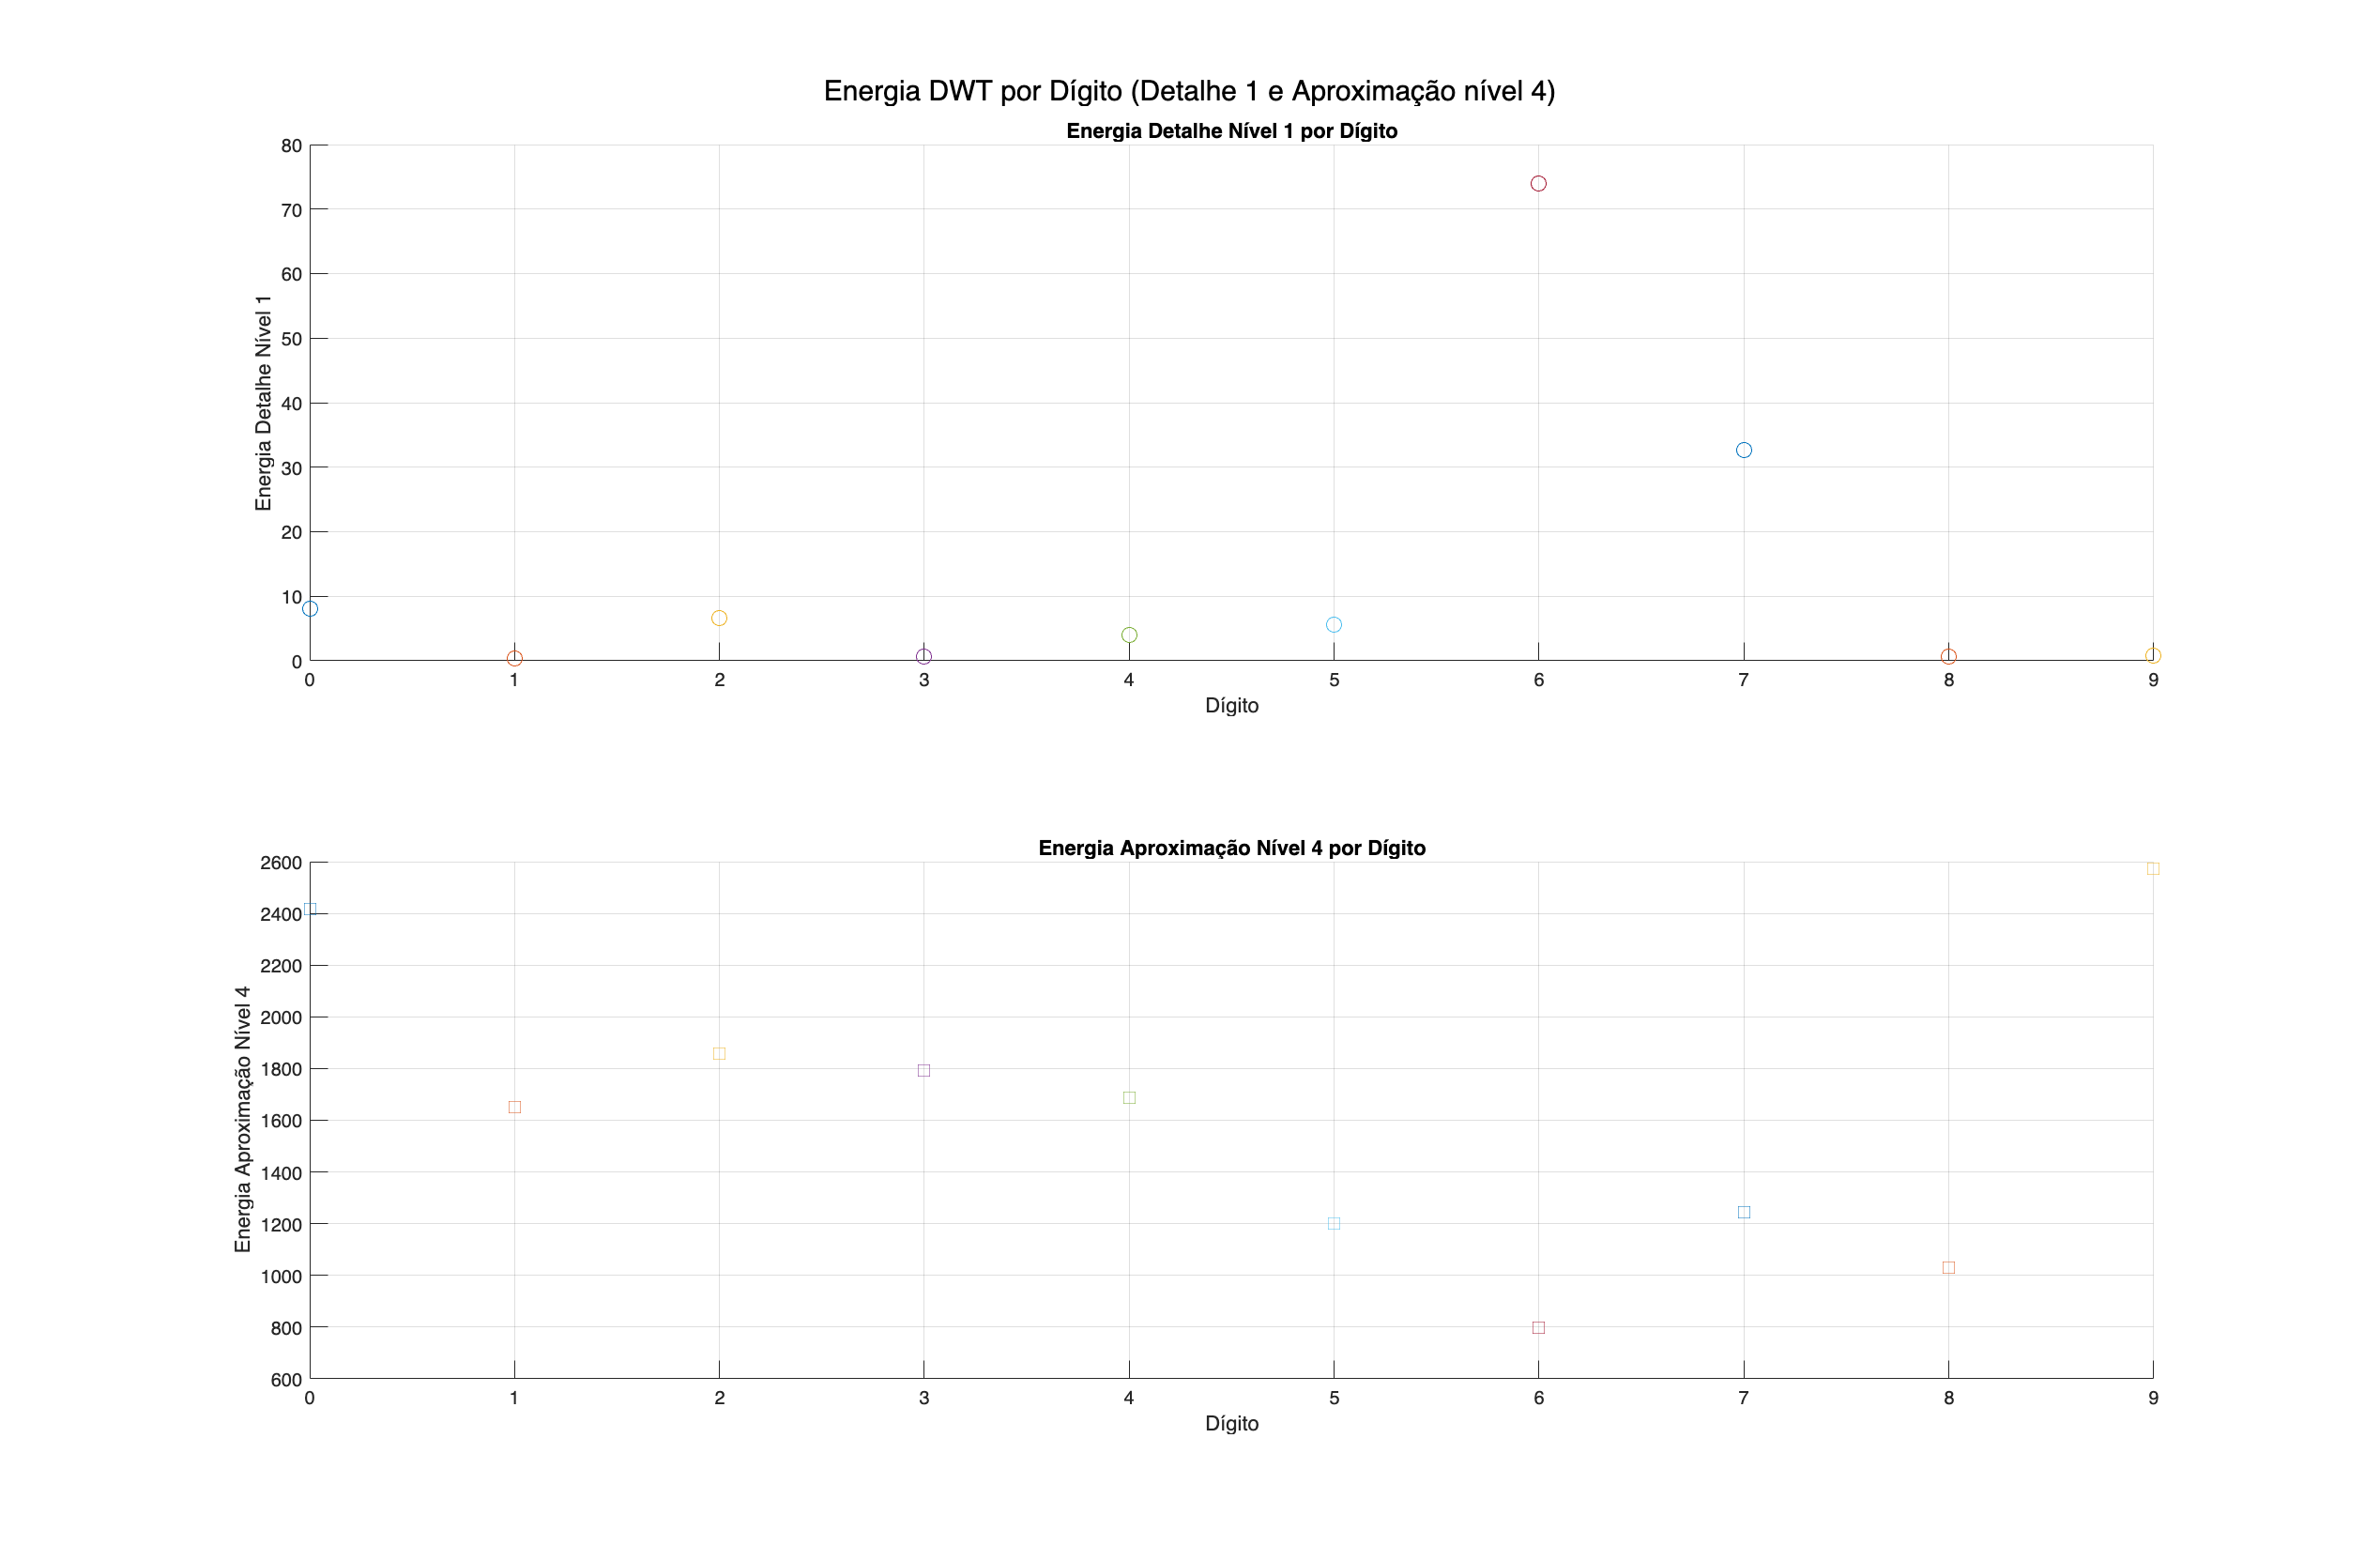


% 2) Distribuição de Energia por Dígito (exemplo para nível de detalhe 1 e aproximação)
figure('Name','Energia DWT por Dígito','NumberTitle','off','Units','normalized','OuterPosition',[0 0 1 1]);
digitos = unique(tabela.Digito);
numD = numel(digitos);
colors = lines(numD);

subplot(2,1,1);
hold on;
for k = 1:numD
    idx = tabela.Digito == digitos(k);
    plot(digitos(k), mean(energiaDet(idx,1)), 'o', 'MarkerSize',8, 'Color',colors(k,:));
end
hold off;
xlabel('Dígito'); ylabel('Energia Detalhe Nível 1');
title('Energia Detalhe Nível 1 por Dígito');
grid on;

subplot(2,1,2);
hold on;
for k = 1:numD
    idx = tabela.Digito == digitos(k);
    plot(digitos(k), mean(energiaAprox(idx,decompLevel)), 's', 'MarkerSize',8, 'Color',colors(k,:));
end
hold off;
xlabel('Dígito'); ylabel(sprintf('Energia Aproximação Nível %d', decompLevel));
title(sprintf('Energia Aproximação Nível %d por Dígito', decompLevel));
grid on;

sgtitle('Energia DWT por Dígito (Detalhe 1 e Aproximação nível 4)');


%% 3) Comparação STFT × DWT (comentários)
% - STFT fornece mapeamento tempo-frequência com resolução fixa: 
%     • Janela curta → boa resolução temporal, pior frequência 
%     • Janela longa → boa resolução em frequência, pior temporal
% - DWT se adapta: níveis altos capturam componentes de baixa frequência (aproximações) com 
%   maior resolução em frequência; níveis baixos capturam alta frequência com melhor resolução temporal.
% - As energias por nível de DWT mostram como a maior parte da energia do dígito se concentra 
%   em determinadas bandas escalares, o que pode ajudar a separar dígitos que possuem 
%   padrões de transição rápida (detalhes) versus lentos (aproximações).
% - Em contraste, STFT média (Ex12) e quartis mostraram comportamentos espectrais fixos, que 
%   podem diluir eventos transientes.
% - Conclusão: para sinais de fala de dígitos, DWT fornece uma representação multirresolução 
%   que pode revelar características discriminantes de detalhes de alta frequência (picos) e 
%   da forma global do sinal (aproximações), complementando a análise STFT.


## Exercício 26: Atualização do arquivo .mat com a tabela completa

% Assumindo que você já calculou:
%   energiaDet (n×decompLevel) e energiaAprox (n×decompLevel)

% Adiciona colunas de energia de detalhe para cada nível
for lev = 1:decompLevel
    nomeCol = sprintf('EnergiaDet_Nivel%d', lev);
    tabela.(nomeCol) = energiaDet(:, lev);
end

% Adiciona coluna de energia de aproximação no nível máximo
tabela.(['EnergiaAprox_Nivel', num2str(decompLevel)]) = energiaAprox(:, decompLevel);

% Salva a tabela atualizada de volta em AED1.mat
save('AED1.mat', 'tabela');
disp('AED1.mat atualizado com as energias DWT (detalhes e aproximação).');

AED1.mat atualizado com as energias DWT (detalhes e aproximação).


disp(tabela);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral    Centroid_Mean    Bandwidth_Mean    Rolloff90_Mean    Flux_Mean    Flatness_Mean    EnergiaDet_Nivel1